## Task 2 (Image Restoration - Noise Filtering) 

#### Corrupt image with Gaussian noise of zero mean and such variance, where the noisy image to have 20dB Signal to Noise Ratio. Apply moving average and median filter to remove the noise from the image


$$\textrm{SNR}=10\;\log_{10} \left(\frac{\textrm{var}\left(\textrm{image}\right)}{\textrm{var}\left(\textrm{noise}\right)}\right)\Rightarrow \frac{\textrm{var}\left(\textrm{image}\right)}{\textrm{var}\left(\textrm{noise}\right)}=10{\;}^{\frac{\textrm{SNR}}{10}} \Rightarrow \textrm{var}\left(\textrm{noise}\right)=\frac{\textrm{var}\left(\textrm{image}\right)}{{10}^{\frac{\textrm{SNR}}{10}} }$$


flower = im2double(load(fullfile("./","flower.mat")).flower);
SNR = 20; % in dB
% Acording to the formula above
noise = var(flower(:))/(10^(SNR/10));
noisy_flower = imnoise(flower, 'gaussian', 0, noise);

#### Normal flower

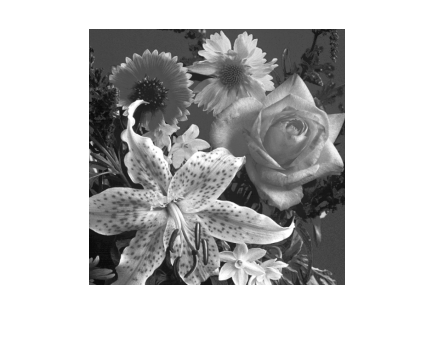

imshow(flower);

#### Flower with noise

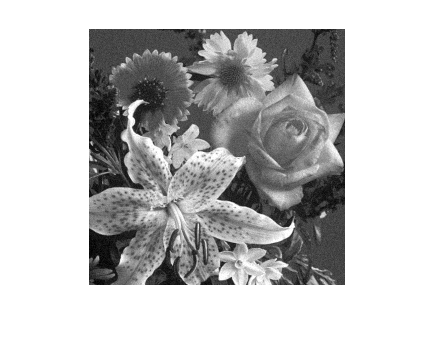

imshow(noisy_flower);

#### Filtering the image with moving average

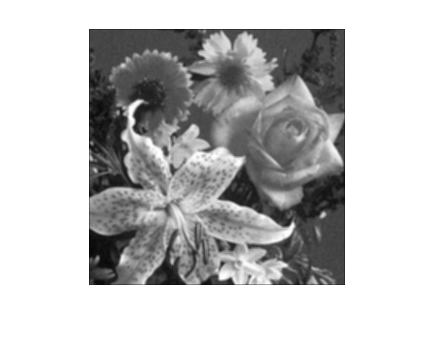

avg = ones(3)./9;
filtered = imfilter(noisy_flower,avg);
imshow(filtered);

#### Filtering the image with median filter

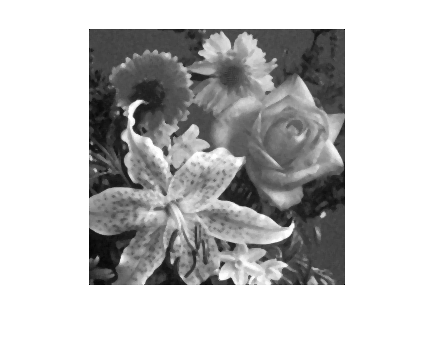

filtered = medfilt2(noisy_flower);
imshow(filtered);

The moving average filter seems to preform better on gaussian noise.

### Corrupt image with salt and pepper noise of 20%. Apply moving average and median filter to remove the noise from the image

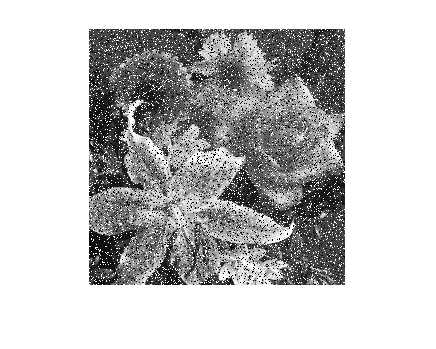

salty_flower = imnoise(flower,'salt & pepper',.2);
imshow(salty_flower)

#### Filtering the image with moving average

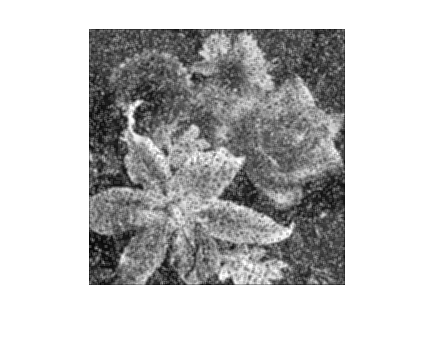

avg = ones(3)./9;
filtered = imfilter(salty_flower,avg);
imshow(filtered);

#### Filtering the image with median filter

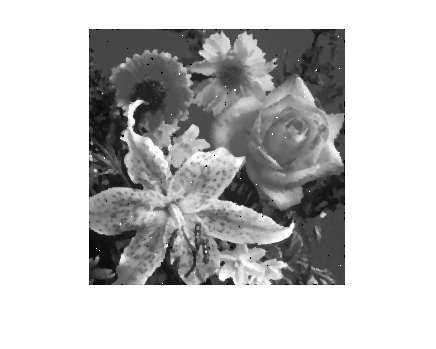

filtered = medfilt2(salty_flower);
imshow(filtered);

The median filters performance is much better than that of the moving average when removing salt and pepper noise. It's als clear that it's easier to remove salt and pepper noise than it is to remove gaussian noise.

### Corrupt the image with Gaussian noise of zero mean and such variance, where the noisy image to have 20dB Signal to Noise Ratio, followed by salt and pepper noise of 20%. Try to restore image with a) moving average filter, b) median filter, c) sequential use of moving average and median filter, based on your preferred order

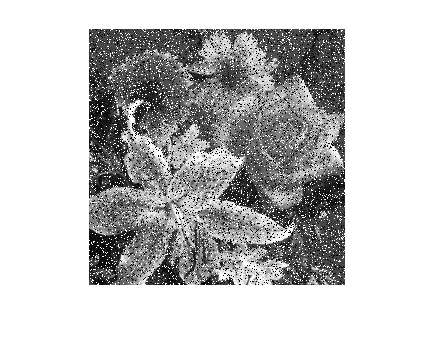

% Create the corrupted file
noise = vn(flower,20);
gaussian_flower = imnoise(flower, 'gaussian', 0, noise);
salty_gaussian_flower = imnoise(gaussian_flower,'salt & pepper',.2);
imshow(salty_gaussian_flower)

### a)

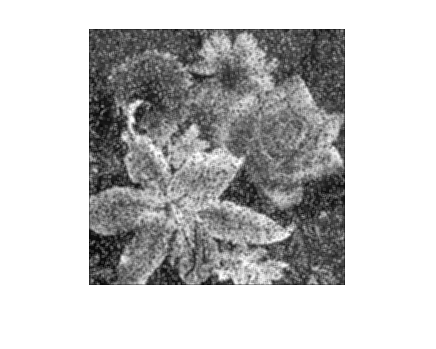

avg = ones(3)./9;
filtered = imfilter(salty_gaussian_flower,avg);
imshow(filtered)

### b)

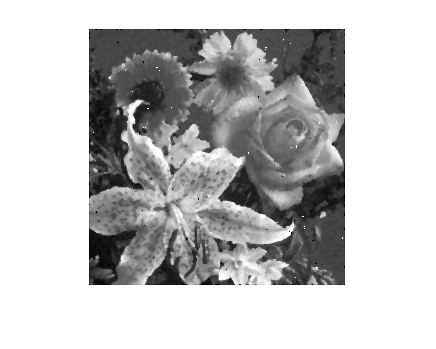

imshow(medfilt2(salty_gaussian_flower))

### c)

Since median filter is better at removing salt and pepper noise, I will use that first

filtered_gaussian_flower = medfilt2(salty_gaussian_flower);
imshow(filtered_gaussian_flower)

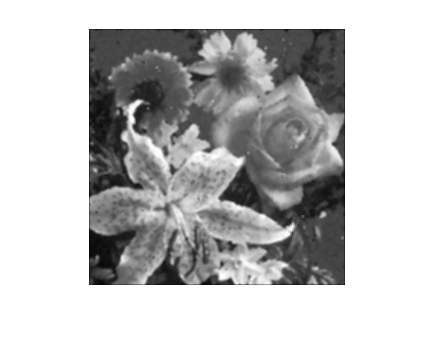

% now apply averaging filter
avg = ones(3)./9;
filtered = imfilter(filtered_gaussian_flower,avg);
imshow(filtered)